% EC 414 - HW 3 - Spring 2022
% DP-Means starter code

(a)

clear, clc, close all,

%% Generate Gaussian data:
% Add code below:
mu1 = [2,2]';
mu2 = [-2,2]';
mu3 = [0, -3.25]';

I2 = [1 0; 0 1];

sigma1 = 0.02 * I2;
sigma2 = 0.05 * I2;
sigma3 = 0.07 * I2;

points = 50;
 
% data1 =  mu1' + randn(points,2)*sigma1;
% data2 =  mu2' + randn(points,2)*sigma2;
% data3 =  mu3' + randn(points,2)*sigma3;
data1 = mvnrnd(mu1, sigma1, points);
data2 = mvnrnd(mu2, sigma2, points);
data3 = mvnrnd(mu3, sigma3, points);

DATA = [data1 ; data2; data3];

mu = [mu1'; mu2'; mu3'];

%% Generate NBA data:
% Add code below:
NBA = readmatrix("NBA_stats_2018_2019.xlsx");
% HINT: readmatrix might be useful here

(b)

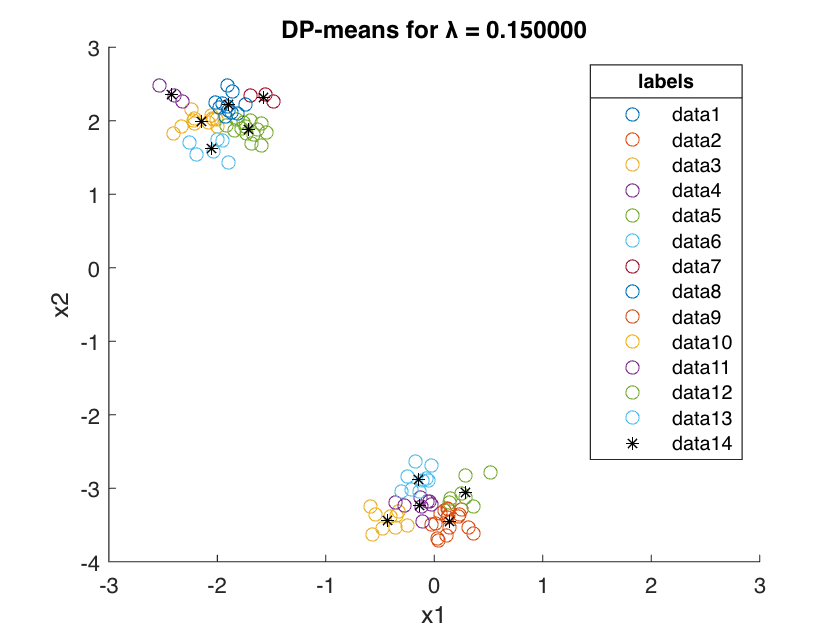

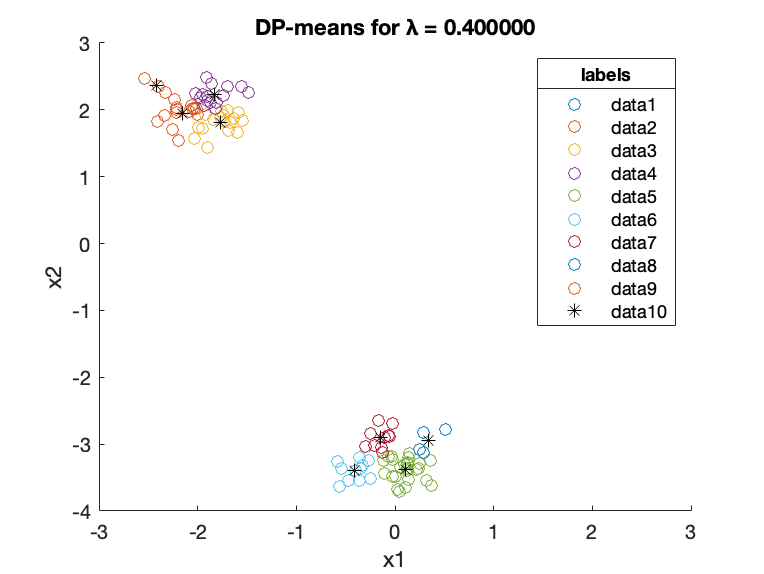

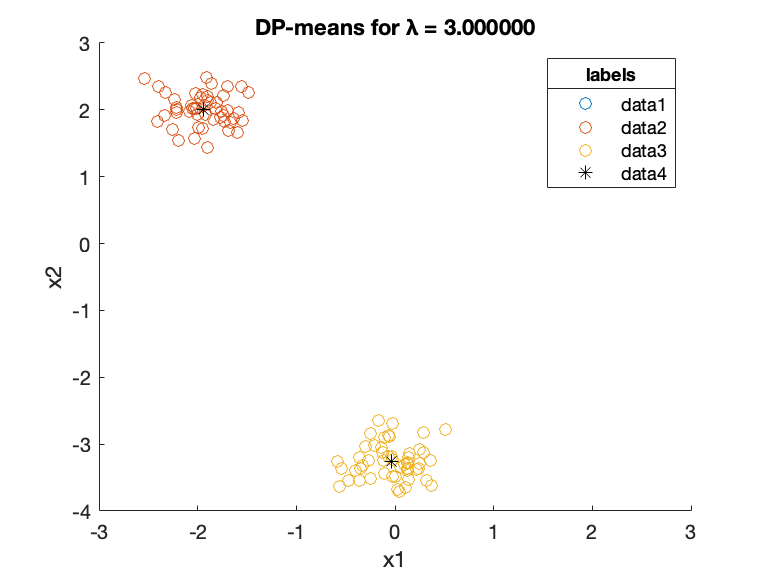

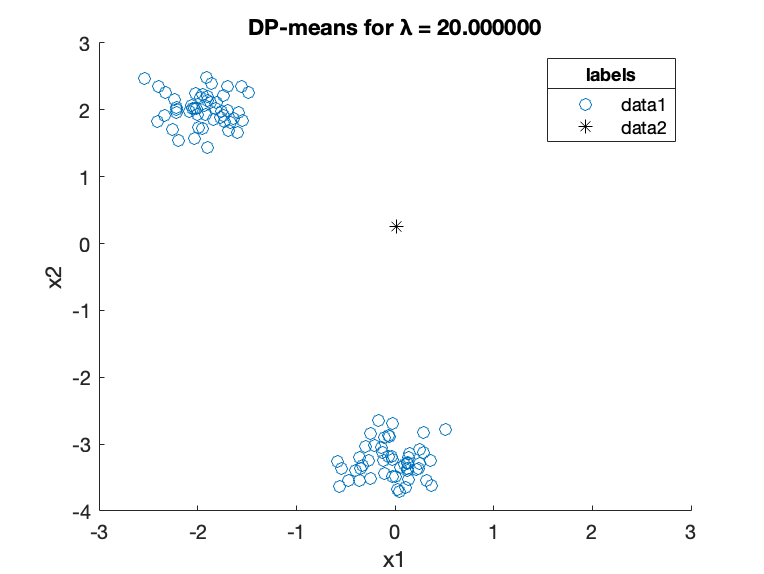

%% (b)
LAMBDA = [0.15 0.4 3 20];
DATA = [data1 ; data2; data3];
for i = 1:length(LAMBDA)
    DP_means(DATA, LAMBDA(i));
end

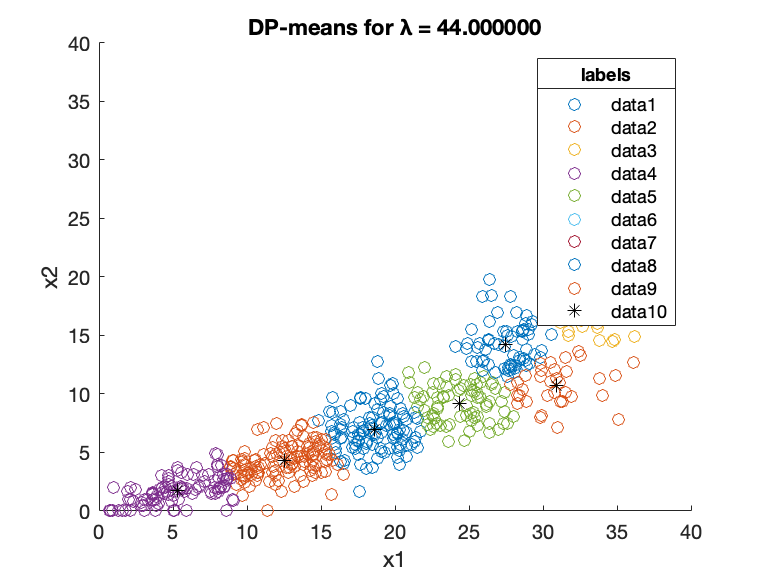

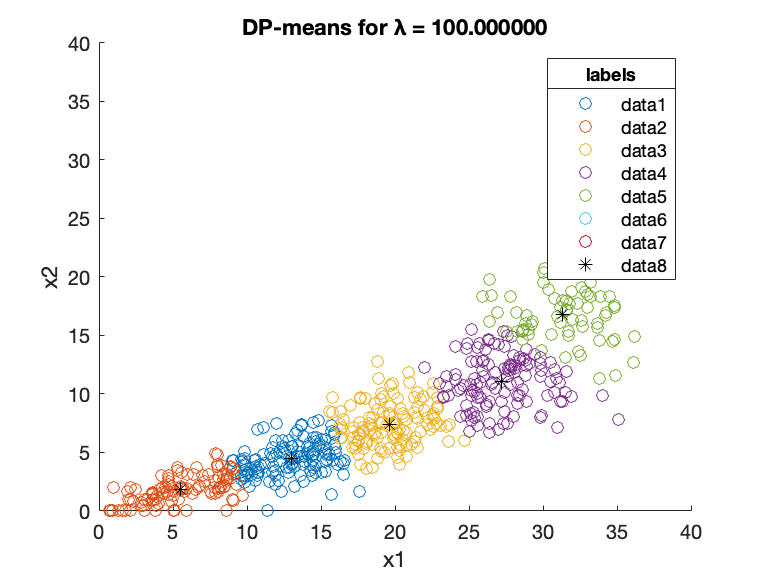

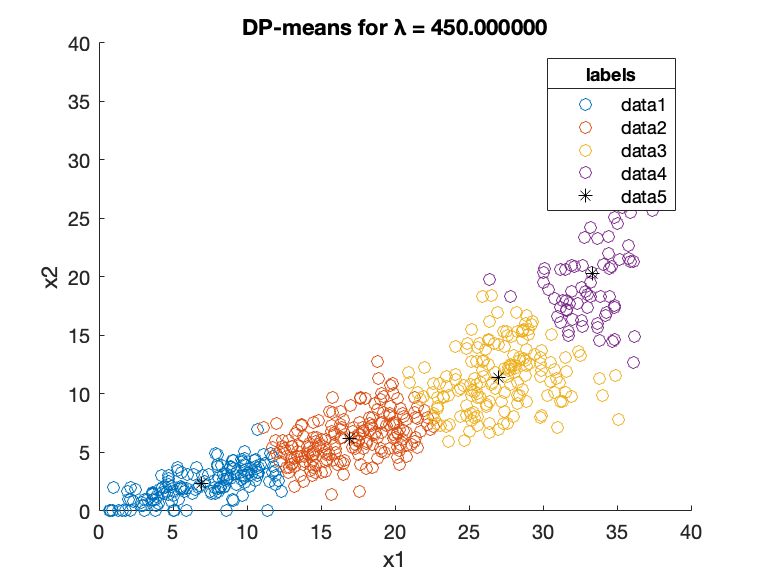

%% (c)
LAMBDA = [44 100 450];
PPG = NBA(:,7);
MPG = NBA(:,5);
DATA = [MPG PPG];
for i = 1:length(LAMBDA)
    DP_means(DATA, LAMBDA(i));
end


%% DP Means method:

function DP_means(DATA, LAMBDA)
    % Parameter Initializations
    
    convergence_threshold = 1;
    num_points = length(DATA);
    total_indices = [1:num_points];
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% DP Means - Initializations for algorithm %%%
    % cluster count
    K = 1;
    prev_K = K;
    current_K = K;
    
    % sets of points that make up clusters
    L = {};
    L = [L [1:num_points]];
    
    % Class indicators/labels
    Z = ones(1,num_points);
    
    % means
    MU = [];
    MU = [MU; mean(DATA,1)];
    prev_MU = MU;
    current_MU = MU;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Initializations for algorithm:
    converged = 0;
    t = 0;
    while (converged == 0)
        t = t + 1;
        %fprintf('Current iteration: %d...\n',t)
        
        %% Per Data Point:
        for i = 1:num_points
            
            %% CODE 1 - Calculate distance from current point to all currently existing clusters
            % Write code below here:
            dist = euclidean_distance(DATA(i,:),MU);
            ind = find(min(dist) == dist);
            Z(i) = ind(1); %if 2 points equidistant choose first index
            %% CODE 2 - Look at how the min distance of the cluster distance list compares to LAMBDA
            % Write code below here:
            if(min(dist)^2 > LAMBDA)
                K = K + 1;
                Z(i) = K;
                MU(K,:) = DATA(i,:);
            end        
        end
        
        %% CODE 3 - Form new sets of points (clusters)
        % Write code below here:
        for i = 1:K
            L{i} = find(Z == i);
        end
        %% CODE 4 - Recompute means per cluster
        % Write code below here:
        for i = 1:K
            MU(i,:) = mean(DATA(L{i},:),1);
        end
        prev_MU = current_MU;
        current_MU = MU;
        prev_K = current_K;
        current_K = K;
        %% CODE 5 - Test for convergence: number of clusters doesn't change and means stay the same %%%
        % Write code below here:
        if(isequal(prev_MU(~isnan(prev_MU)), current_MU(~isnan(current_MU))) && prev_K == current_K)
            converged = 1;
        end
        %% CODE 6 - Plot final clusters after convergence 
        % Write code below here:
        
        if (converged)
            MU(isnan(MU(:,1)),:) = [];
            titl = sprintf('DP-means for λ = %f',LAMBDA);
            figure()
            hold on
            for i = 1:K
                if(~isempty(L{i}))
                    scatter(DATA(L{i},1),DATA(L{i},2))
                end
            end
            scatter(MU(:,1),MU(:,2),'black*');
            xlabel('x1')
            ylabel('x2')
            title(titl)
            legend
            title(legend,'labels')
            hold off
            [K,c] = size(MU);
            %%%%
        end    
    end
end




%% Functions
%returns euclidean distance of a singular point to each point in a matrix
function distance = euclidean_distance(point, points)
    [r,c] = size(points);
    distance = zeros(r,1); %initialize distance vector
    for (i = 1:r) % loop through each point of the matrix of points
        distance(i,1) = sqrt((point(1,1)-points(i,1))^2+(point(1,2)-points(i,2))^2); %distance between two points
    end
end




